%% uncertainty.m
%
% Author:   Lincoln Scheer
% Date:     7 March 2024
%
% This script file is for calculating the low and high range of detectable
% fluxes for our dynamic flux chamber. This simulations assumes perfect
% mixing and steady state calculations.

clear, clc, close all

**Theory**

Sources of Uncertainty

- Sensor Accuracy

- Mixing Rates

- Steady State Calculations

- Measurement Duration Period

- Flux Averaging / Interpolation Methodologies

Goals

- Maximize Chamber CO2

- Minimize Uncertainty

**What this Program Does**

This program calculates the measurement resolution of our CO2 flux chamber given chamber parameters and environmental assumptions.

% System Assumptions

% Chamber
w_As = 0.064844702; % [m^2]
w_V  = 0.015220183; % [m^3]

% Environment Assumptions
P = 101325; % [Pa]
T = 293.15; % [K]

% Flux Ranges
F_l = 0.5; % [umol/m^2/s]
F_h = 10; % [umol/m^2/s]

% CO2 Ambient Concentration
Camb = 416; % [ppm]

% Pump Flow Rate Range
Q = 2; %[lpm]

% CO2 Meas. Uncertainty
uC = 1.1282; % [ppm]

% Flow Meas. Uncertainty
uQ = 0.33; % [lpm]

% Unit Conversion Anonymous Functions
ppm_to_mol = @(ppm) (ppm*P)/(1e6*8.314*T);
mol_to_ppm = @(mol) (1e6*8.314*mol*T)/P;
lpm_to_cms = @(lpm) lpm/60000;
cms_to_lpm = @(cms) cms*60000;

% Converting Values to Working Units
w_Camb = ppm_to_mol(Camb);     % ppm to mol/m2
w_uC = ppm_to_mol(uC);         % ppm to mol/m2
w_Q = lpm_to_cms(Q);           % lpm to cms
w_uQ = lpm_to_cms(uQ);         % lpm to cms
w_F_l = F_l * 1e-6;            % umol to mol
w_F_h = F_h * 1e-6;            % umol to mol

% Governing Equations Anonymous Functions

% Chamber Concentration Non-Steady State
Cchmb = @(Camb, F, As, Q, t, V) Camb + (F.*As./Q).*(1-exp(-Q.*t./V));

% Chamber Concentration Steady State
Cchmb_tss = @(Camb, F, As, Q) Camb + (F.*As)./Q;

% Uncertainty in Flux Measurement
uF = @(dC, As, uQ, uC, Q) sqrt( (dC.*uQ./As).^2 + ((2.*Q.*uC)./As).^2 );

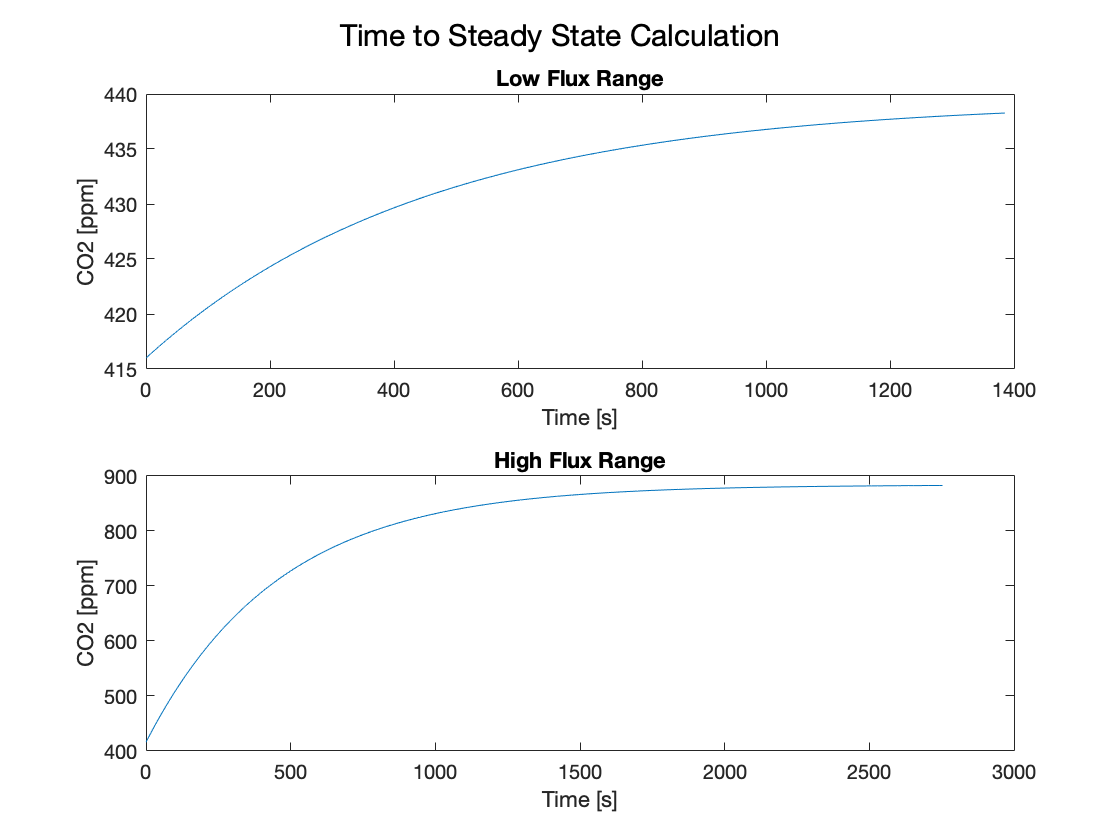

% Finding Time to Steady State & Steady State Chamber CO2
t0 = 0;
dt = 1;
[tss_data_l, tss_l, Cchmb_l] = CO2CHAMBERTSS(Cchmb, 1, w_Camb, w_F_l, w_As, w_Q, t0, w_V, w_uC);
[tss_data_h, tss_h, Cchmb_h] = CO2CHAMBERTSS(Cchmb, 1, w_Camb, w_F_h, w_As, w_Q, t0, w_V, w_uC);

fig1 = figure();
subplot(2, 1, 1)
plot(tss_data_l.TIME, mol_to_ppm(tss_data_l.CO2))
xlabel("Time [s]")
ylabel("CO2 [ppm]")
title("Low Flux Range")
subplot(2, 1, 2)
plot(tss_data_h.TIME, mol_to_ppm(tss_data_h.CO2))
xlabel("Time [s]")
ylabel("CO2 [ppm]")
title("High Flux Range")
sgtitle("Time to Steady State Calculation")


% calculate difference between chamber and ambient concentration
w_dC_l = Cchmb_l - w_Camb;                              
w_dC_h = Cchmb_h - w_Camb;  

% calculate flux uncertainty for high and low ranges
uF_l = uF(w_dC_l, w_As, w_uQ, w_uC, w_Q)*1e6;           
uF_h = uF(w_dC_h, w_As, w_uQ, w_uC, w_Q)*1e6;

% Organizing Data
columns = ["q", "c_chmb_low", "c_chmb_high", "t_at_tss_low", "t_at_tss_high", "dc_low", "dc_high", "uf_low", "uf_high"];
data = [cms_to_lpm(w_Q)' ,mol_to_ppm(Cchmb_l)', mol_to_ppm(Cchmb_h)', tss_l', tss_h', mol_to_ppm(w_dC_l)', mol_to_ppm(w_dC_h)', uF_l', uF_h'];

data = array2table(data, 'VariableNames', columns);
data.f_meas_l = F_l + data.uf_low;

data.f_meas_h = F_h - data.uf_high;



% Final Data

vars = rows2vars(data);
vars.OriginalVariableNames = ["Flow"; "Chamber CO2 @ HIGH"; "Chamber CO2 @ LOW"; "Steady State Time @ LOW"; "Steady State Time @ HIGH";  "Chamber to Ambient CO2 Difference @ LOW"; "Chamber to Ambient CO2 Difference @ HGIH"; "Flux Uncertainty @ LOW"; "Flux Uncertainty @ HIGH"; "Measurable Flux @ LOW"; "Measurable Flux @ HIGH"];
vars.Units = ["LPM"; "PPM"; "PPM"; "S"; "S"; "PPM"; "PPM"; "UMOL/M^2/S"; "UMOL/M^2/S"; "UMOL/M^2/S"; "UMOL/M^2/S"];

disp(vars)

              OriginalVariableNames                 Var1         Units    
    __________________________________________    ________    ____________

    "Flow"                                               2    "LPM"       
    "Chamber CO2 @ HIGH"                             439.4    "PPM"       
    "Chamber CO2 @ LOW"                             883.93    "PPM"       
    "Steady State Time @ LOW"                         1386    "S"         
    "Steady State Time @ HIGH"                        2754    "S"         
    "Chamber to Ambient CO2 Difference @ LOW"       23.396    "PPM"       
    "Chamber to Ambient CO2 Difference @ HGIH"      467.93    "PPM"       
    "Flux Uncertainty @ LOW"                      0.095559    "UMOL/M^2/S"
    "Flux Uncertainty @ HIGH"                       1.6507    "UMOL/M^2/S"
    "Measurable Flux @ LOW"                        0.59556    "UMOL/M^2/

writetable(vars, 'measurement_range_results.csv')

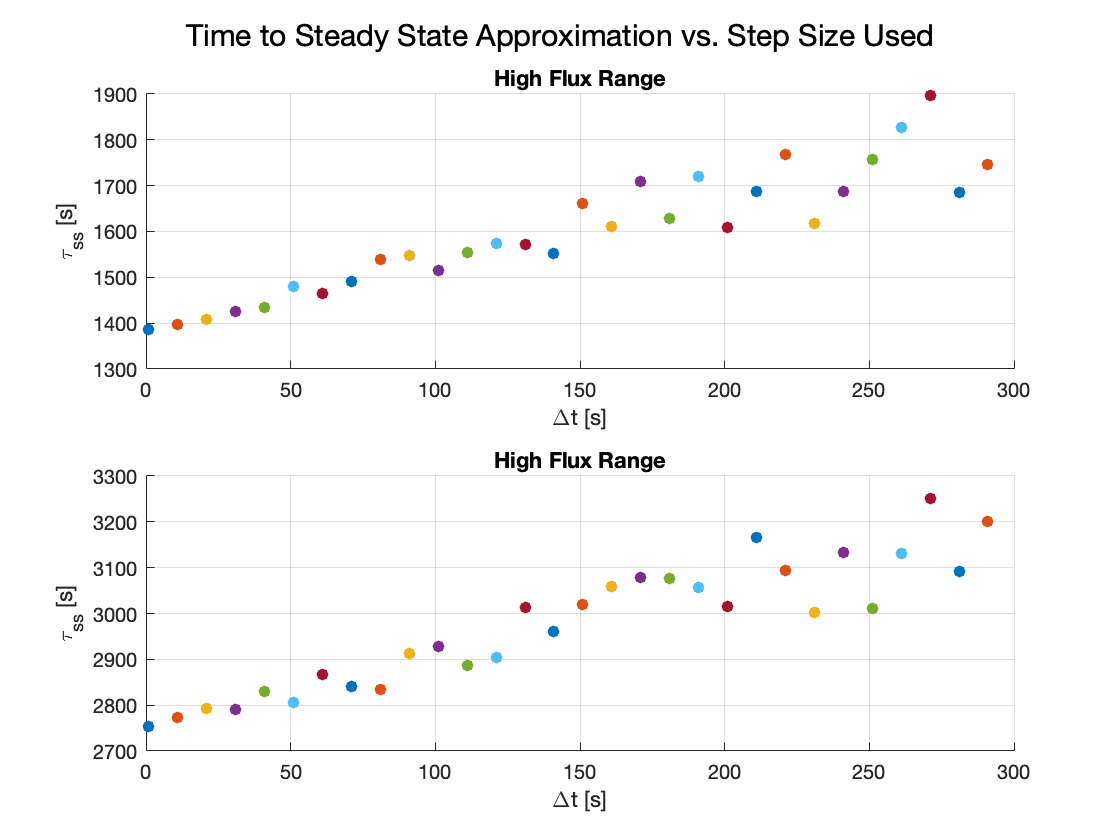

% TSS Experiments

t0 = 0;
dt_min = 1;
dt_max = 60*5;
dt_step = 10;

fig = figure();
subplot(2, 1, 1)
grid on
hold on

tss_ls = zeros(2, 0);
for dt = dt_min:dt_step:dt_max
    [tss_data_l, tss_l, Cchmb_l] = CO2CHAMBERTSS(Cchmb, dt, w_Camb, w_F_l, w_As, w_Q, t0, w_V, w_uC);
    scatter(dt, tss_l, 'filled', 'o');
    tss_ls = [tss_ls, tss_l];
end
ylabel("\tau_{ss} [s]")
xlabel("\Delta{t} [s]")
title("High Flux Range")
subplot(2, 1, 2)
grid on
hold on

tss_hs = zeros(2, 0);
for dt = dt_min:dt_step:dt_max
    [tss_data_h, tss_h, Cchmb_h] = CO2CHAMBERTSS(Cchmb, dt, w_Camb, w_F_h, w_As, w_Q, t0, w_V, w_uC);
    scatter(dt, tss_h, 'filled', 'o');
    tss_hs = [tss_hs, tss_h];
end
ylabel("\tau_{ss} [s]")
xlabel("\Delta{t} [s]")
title("High Flux Range")


sgtitle("Time to Steady State Approximation vs. Step Size Used") 

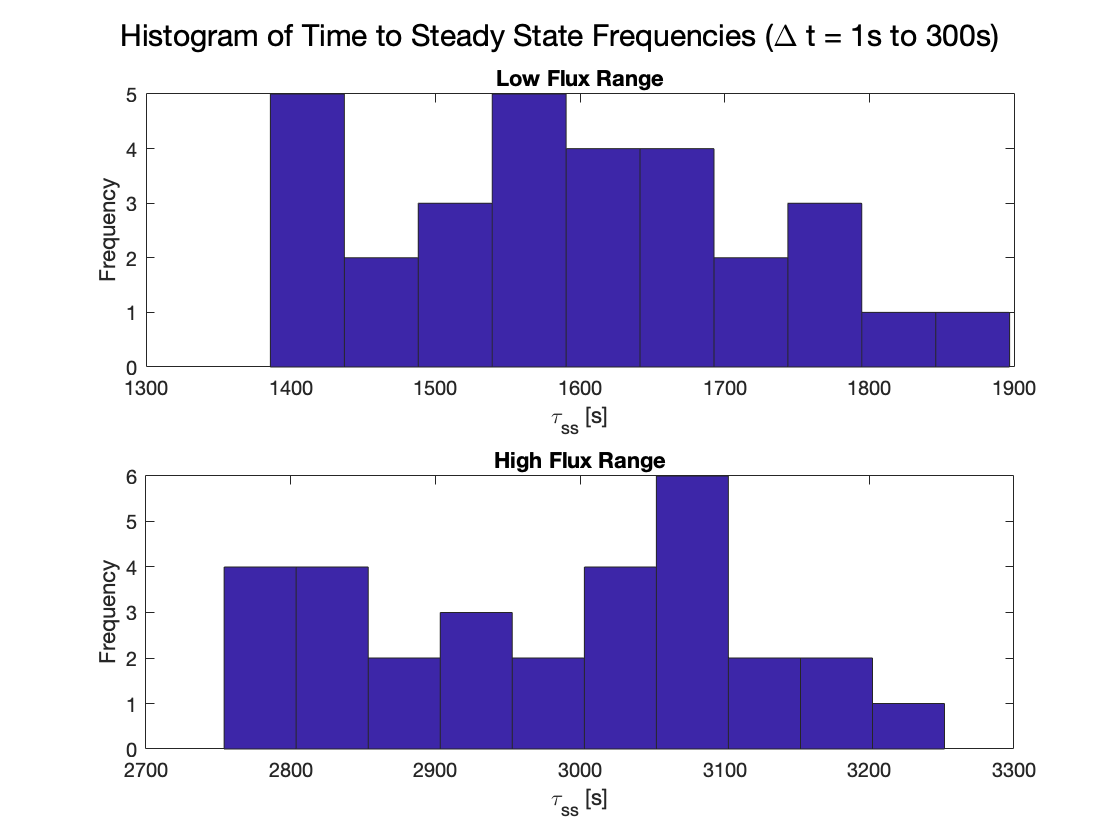


fig2 = figure();
subplot(2, 1, 1)
hist(tss_ls)
xlabel("\tau_{ss} [s]")
ylabel("Frequency")
title("Low Flux Range")
subplot(2, 1, 2)
hist(tss_hs)
xlabel("\tau_{ss} [s]")
ylabel("Frequency")
title("High Flux Range")
sgtitle("Histogram of Time to Steady State Frequencies (\Delta t = " + dt_min+ "s to "+ dt_max + "s)") 


set(gcf,'PaperType','A4')
%exportgraphics(fig, "fig.png")
%exportgraphics(fig1, "fig1.png")
%exportgraphics(fig2, "fig2.png")